## Project: CSTR Temperature Control Using PID in MATLAB

% CSTR(Continous Stirred Tank Reactor)
% PID Controller(Proportional , Integral , Derivative)
% Energy Balance: dT/dt = (1/tau)*(T_sp - T) + Q + disturbance
% PID Equation: Q(t) = Kp*e(t) + Ki*integral_e(t) + Kd*de(t)/dt
% Error = T_sp - T
% Integral = Integral + error * dt
% Derivative = (error - prev_error)/dt

% Intialize Parameters

tspan = 0:0.1:200 %Time from 0 to 200 s with step of 0.1s

tspan =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


T_sp  = 50;
T0    = 25;
tau   = 10;        %Time constant(10s)
Kp    = 2;         %Proportional gain
Ki    = 0.1;       %Integral gain
Kd    = 0.5       %Derivative gain

Kd = 0.5000

% Intializing Arrays to store data
T          = zeros(size(tspan)); %Temperature Array - Starting with Zeros
T(1)       = T0; %set intial temperature
Q          = zeros(size(tspan)); %Arary for heat jacket input
integral   = 0;
prev_error = 0;
dt         = tspan(2) - tspan(1);

% Simulation Loop
for i = 1:length(tspan) - 1;
    T_current = T(i);
    error = T_sp - T_current; %calculating the error
    integral = integral + error * dt; %sums error over time
    derivative = (error - prev_error)/dt; %How fast the error changes is derivative
    Q(i) = Kp*error + Ki*integral + Kd*derivative; %PID equation
    Q(i) = max(0,min(Q(i),10)); %Keeping Heat input between 0 and 10
    disturbance = 0; 
    if tspan(i) >= 100
        disturbance = -5; %Adding a cooling effect at 100s to see if PID can Handle it
    end
 %Updating Temperature Using Energy Balance
    dTdt = (1/tau)*(T_sp - T) + Q(i) + disturbance;
    T(i + 1) = T(i) + dt*dt/dt; % Updating Temperature
    prev_error = error;
end

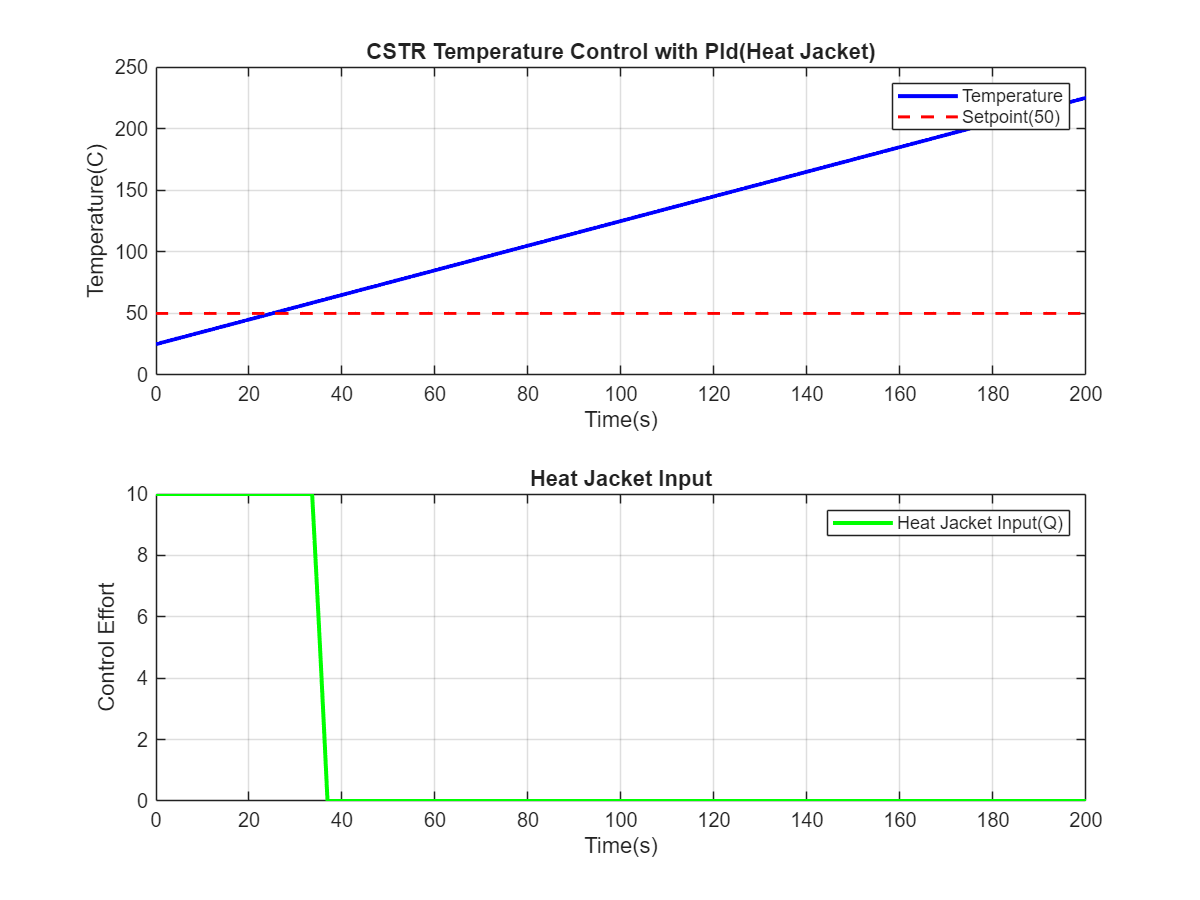

% Plotting my results
figure('Position',[100,100,800,600]);
subplot(2,1,1); % First plot for temperature
plot(tspan,T,'b','LineWidth',2,'DisplayName','Temperature'); % showing setpoint
hold on;
plot(tspan,T_sp*ones(size(tspan)),'r--','LineWidth',1.5,'DisplayName','Setpoint(50)'); % Showing setpoint
title('CSTR Temperature Control with PId(Heat Jacket)');
xlabel('Time(s)');
ylabel('Temperature(C)');
legend('show');
grid on;

subplot(2,1,2); % Second plot for heat jacket input
plot(tspan,Q,'g','Linewidth',2,'DisplayName','Heat Jacket Input(Q)'); % Plotting Q vs time
title('Heat Jacket Input');
xlabel('Time(s)');
ylabel('Control Effort');
legend('show');
grid on;


saveas(gcf,'cstr_pid_plots.png');

saveas(gcf,'cstr_pid_plots.png');





